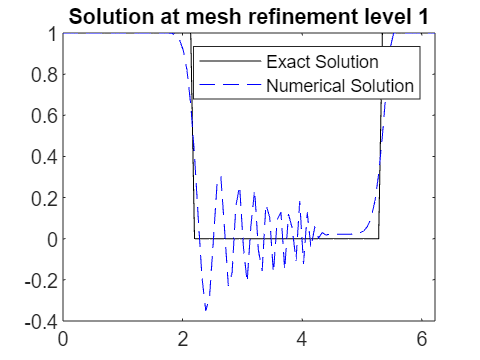

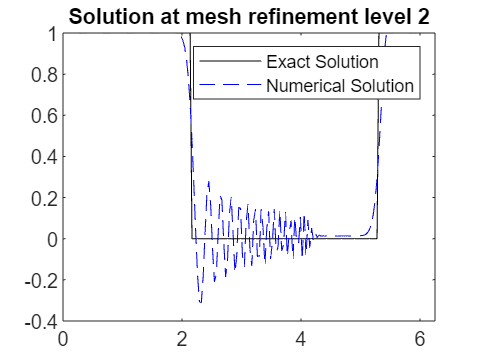

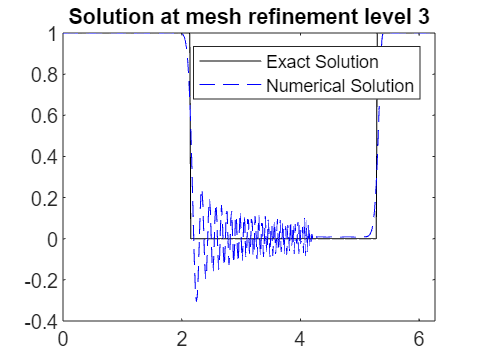

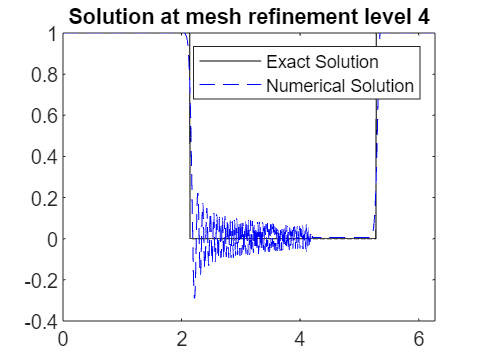

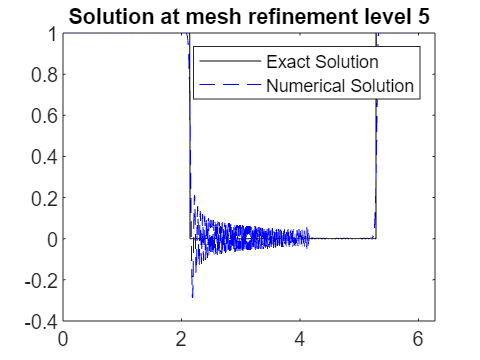

% Sanaz Hami
% 1D Linear Advection with Periodic Initial Condition integrated with DR

% Initialization of parameters
xa = 0;
xb = 2 * pi;
T = 1;
lambda_DR = 0.5; % Relaxation parameter for DR
epsilon = 1e-6; % Convergence criterion for DR
max_iter = 1000; % Maximum iterations for DR
m = -1; % Define lower bound for DR
M = 1; % Define upper bound for DR
v0 = @(x) double(mod(x, 2*pi) < pi); % New initial condition
errtab = zeros(5, 2);
verbose = false; % Set to false to avoid extra output

% Main loop for mesh refinement
for kk = 1:5
    Nx = 100 * (2 ^ (kk - 1)) - 1;
    h = (xb - xa) / (Nx + 1);
    k = h^2;
    v = zeros(1, Nx + 3);
    x = linspace(xa, xb - h, Nx + 1);
    v(2:Nx + 2) = v0(x);
    v(1) = v(Nx + 2); % Ghost point for the right boundary
    v(Nx + 3) = v(2); % Ghost point for the left boundary

    % Time marching
    for ii = 1:floor(T / k)
        v_new = zeros(size(v));
        for jj = 2:Nx + 2
            v_new(jj) = v(jj) + ((k / h) / 2) * (v(jj + 1) - v(jj - 1));
        end
        v_new(1) = v_new(Nx + 2); % Periodic boundary conditions
        v_new(Nx + 3) = v_new(2); % Periodic boundary conditions
        v = v_new;

        % Call DR function after each time step
        u_guess = v(2:Nx+2); % Use the current solution as the initial guess
        v(2:Nx+2) = DR(m, M, v(2:Nx+2), u_guess, epsilon, max_iter, lambda_DR, verbose); % Post-process the solution
    end

    % Calculate numerical error at the current mesh refinement level
    u_exac = v0(x + T);
    errtab(kk, 1) = sqrt(sum((u_exac - v(2:Nx + 2)).^2 * h));

    % Plot the solution
    figure;
    plot(x, u_exac, 'k-', x, v(2:Nx + 2), 'b--');
    legend('Exact Solution', 'Numerical Solution');
    title(sprintf('Solution at mesh refinement level %d', kk));
    drawnow; % Update the plot
end


% Compute the order of accuracy for each mesh refinement level
for kk = 2:5
    errtab(kk, 2) = log(errtab(kk - 1, 1) / errtab(kk, 1)) / log(2);
end

% Display the complete error table after all calculations
format shortE;
disp(errtab); % Display the error table

   3.3106e-01            0
   2.6782e-01   3.0580e-01
   2.1725e-01   3.0191e-01
   1.8602e-01   2.2393e-01
   1.3672e-01   4.4424e-01




% Define the DR function with verbose flag

function [u_mod] = DR(m, M, u, u_guess, epsilon, max_iter, lambda, verbose)
    % Initialization
    N = length(u); % Number of elements in u
    b = sum(u); % Sum of u, which should be preserved
    u_mod = u_guess; % Initial guess for the modified solution

    % Douglas-Rachford iteration
    for iter = 1:max_iter
        % Reflect and project
        y = u_mod + lambda * (b/N - sum(u_mod)/N);
        y = max(min(y, M), m);
        y_next = u_mod + lambda * (y - u_mod);

        % Update u_mod
        u_mod = y_next;

        % Check for convergence
        if norm(u_mod - u_guess, 2) <= epsilon
            if verbose
                fprintf('Converged in %d iterations.\n', iter);
            end
            break;
        end
    end

    % If not converged, issue a warning
    if iter == max_iter && verbose
        warning('Maximum iterations reached without convergence.');
    end
end

